## Submission for HW04

clear;

addpath('/Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/matlab_utils/');
addpath('/Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/products/');
addpath('/Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/hw04/');

obsfile = ['/Users/p3choi/SIOG230_GNS_Geodesy/' ...
    'SIOG230_GNS_Geodesy/products/opmt2920.19o'];

[obs,t,gps,~,~] = ...
    read_rinexo(obsfile);

-------------
Reading /Users/p3choi/SIOG230_GNS_Geodesy/SIOG230_GNS_Geodesy/products/opmt2920.19o
  approximate position (m): 4202777.622 171367.761 4778659.984
  7 observable types: L1L2C1P1P2S1S2
  sampling interval: 30 seconds
  2880 epochs
  30 GPS satellites
  0 GLONASS satellites
  0 GALILEO satellites
  reading file body -- this part is slow, sorry...


% % % Find MP1 MP2 for PRN=3
% 
% sv = 3;
% f1 = 1.57542*1e9;
% f2 = 1.2276*1e9;
% range = [1:2880];
% [MP1_sv, MP2_sv, t_hrs] = compute_MP(obsfile, sv, f1, f2, range);
% 
% clf;
% plot(t_hrs, MP1_sv,"b",LineWidth=1);
% title("MP1 for PRN"+sv);
% xlabel("Time (Hours)");
% ylabel("MP1 (m)");
% 
% clf;
% plot(t_hrs, MP2_sv,"b",LineWidth=1);
% title("MP2 for PRN"+sv);
% xlabel("Time (Hours)");
% ylabel("MP2 (m)");


% % Find MP1 MP2 for PRN=10
%%% Define ranges based on prior knowledge of NaNs
% temp = obs.L1;  % use to find NaNs
sv = 10;
f1 = 1.57542*1e9;
f2 = 1.2276*1e9;

range1 = 499:1123;
range1_1 = 1124:2338;
range2 = 2339:2371;
range2_1 = 2372:2376;
range3 = 2377:2484;
range3_1 = 2485:2554;
range4 = 2555:2639;

ranges = {range1; range1_1; range2; ...
    range2_1; range3; range3_1; range4};

MP1 = double.empty();
MP2 = double.empty();
t_arr = double.empty();

for i = 1:length(ranges)
    [MP1_1, MP2_1, t1] = ...
        compute_MP(obs, t, gps, sv, f1, f2, ranges{i});
    MP1 = cat(1, MP1, MP1_1);
    MP2 = cat(1, MP2, MP2_1);
    t_arr = cat(1, t_arr, t1);
end

disp(t_arr.')

    4.1500    4.1583    4.1667    4.1750    4.1833    4.1917    4.2000    4.2083    4.2167    4.2250    4.2333    4.2417    4.2500    4.2583    4.2667    4.2750    4.2833    4.2917    4.3000    4.3083    4.3167    4.3250    4.3333    4.3417    4.3500    4.3583    4.3667    4.3750    4.3833    4.3917    4.4000    4.4083    4.4167    4.4250    4.4333    4.4417    4.4500    4.4583    4.4667    4.4750    4.4833    4.4917    4.5000    4.5083    4.5167    4.5250    4.5333    4.5417    4.5500    4.5583    4.5667    4.5750    4.5833    4.5917    4.6000    4.6083    4.6167    4.6250    4.6333    4.6417    4.6500    4.6583    4.6667    4.6750    4.6833    4.6917    4.7000    4.7083    4.7167    4.7250    4.7333    4.7417    4.7500    4.7583    4.7667    4.7750    4.7833    4.7917    4.8000    4.8083    4.8167    4.8250    4.8333    4.8417    4.8500    4.8583    4.8667    4.8750    4.8833    4.8917    4.9000    4.9083    4.9167    4.9250    4.9333    4.9417    4.9500    4.9583    4.9667    4.9750

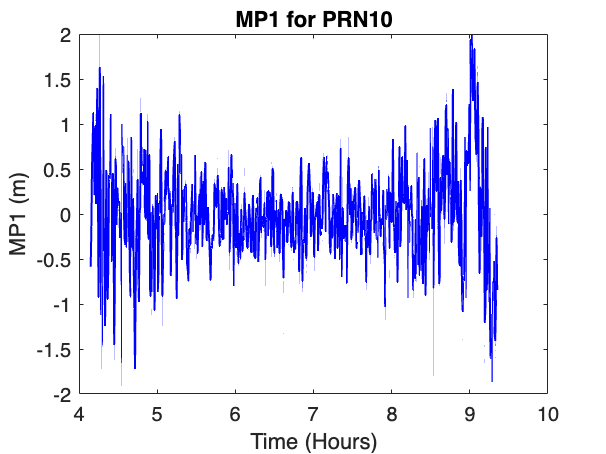


clf;
plot(t_arr.', MP1.',"b",LineWidth=1);
title("MP1 for PRN"+sv);
xlabel("Time (Hours)");
ylabel("MP1 (m)");

clf;
plot(t_arr, MP2,"b",LineWidth=1);
title("MP2 for PRN"+sv);
xlabel("Time (Hours)");
ylabel("MP2 (m)");